# Analisis dinámico del aerotaxi

clear; clc

% Especificaciones "del orden" del City Airbus: 

% masa
m = 2000       % kg

m = 2000

g = 9.8;        % m/s²
Fg = m*g;       % peso en N

% Inercia de caja 4.0 x 2 x 1.5 m3
x = 4.0; y = 2.0; z = 1.5;
% En realidad nuestro dron ocupa una caja de 25x25x4.5 cms
Ix = 1/12 * m * (y^2 + z^2);
Iy = 1/12 * m * (x^2 + z^2);
Iz = 1/12 * m * (x^2 + y^2);
inertia = [ Ix  0   0
            0   Iy  0 
            0   0   Iz]

inertia = 1.0e+03 *

    1.0417         0         0
         0    3.0417         0
         0         0    3.3333


## Fuerza de sustentación

En esta ocasión, los rotores son asimétricos con respecto al eje Y.


% distancia del tren delantero al CM
dNx = 0.50;     
dNy = 1.95;     
% distancia del tren trasero al CM
dSx = 2.50;   
dSy = 1.55;
% altura de los rotores respecto del CM
h   = 0.60;    

% Sustentación con los 4 rotores
syms FT_N FT_S
eqs = [  2*(FT_N + FT_S) == m * g
                 FT_N*dNx == FT_S*dSx    ];
sol = solve(eqs, [FT_N FT_S]);

FT_N_hov = eval(sol.FT_N);
FT_S_hov = eval(sol.FT_S);



% Sustentación con 2 rotores cruzados
eqs = [  FT_N + FT_S == m * g
             FT_N*dNx == FT_S*dSx    ];
sol = solve(eqs, [FT_N FT_S]);

FT_N_hov2 = eval(sol.FT_N);
FT_S_hov2 = eval(sol.FT_S);






## Fuerza de empuje aerodinámico

Según bibliografía, el rotor de un helicóptero de tamaño medio (1400kgm) gira a 300 RPM en sustentación. 

Nosotros asumiremos para nuestro cuadricóptero que se sustenta con los 4 rotores a 400 RPM (las aspas son mucho más pequeñas por lo que generan menos empuje).

Calculamos $\textrm{FT}=\textrm{kFT}*w^2$

% asumiendo velocidad de sustentación con 4 rotores = 400rpm
w_hov = convangvel(400,'rpm','rad/s')

w_hov = 41.8879

kFT_N = FT_N_hov / w_hov^2  

kFT_N = 4.6544

kFT_S = FT_S_hov / w_hov^2  

kFT_S = 0.9309

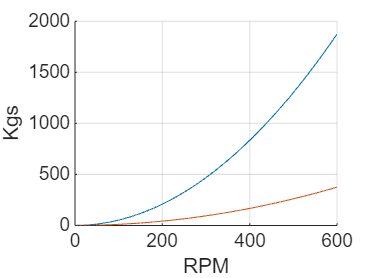


clf
grid on
hold on
xlabel('RPM')
ylabel('Kgs')

rpm = 0:10:600;
radps = convangvel(rpm,'rpm','rad/s');
FT_N = kFT_N * radps.^2;
FT_S = kFT_S * radps.^2;
plot(rpm, FT_N/g)
plot(rpm, FT_S/g)



% La sustentación con 2 rotores requiere que estos se muevan a 565 rpm
% tenemos margen hasta el máximo
w_N_hov2 = sqrt( FT_N_hov2 / kFT_N );
w_S_hov2 = sqrt( FT_S_hov2 / kFT_S );
convangvel( w_N_hov2, 'rad/s','rpm')

ans = 565.6854

convangvel( w_S_hov2, 'rad/s','rpm')

ans = 565.6854

  


% Asumiendo velocidad maxima del rotor de 600rpm
w_max = convangvel(600,'rpm','rad/s') 

w_max = 62.8319

% obtenemos  
P_N_max = kFT_N * w_max.^2 /g   % peso máximo soportado por cada rotor delantero

P_N_max = 1.8750e+03

P_S_max = kFT_S * w_max.^2 /g   % peso máximo soportado por cada rotor trasero

P_S_max = 375

P_max = 2*P_N_max + 2*P_S_max   % peso máximo del aparato

P_max = 4.5000e+03

## Momento de arrastre de los rotores

Momento que experimenta el rotor en sentido contrario a su velocidad de giro:

MDR = kMDR * w². 

Asumimos que:

- No hay rozamiento con el aire 

- El dron está estabilizado

- Si solo contamos con el arrastre de un motor delantero, el dron tarda 2 segundos en alcanzar una velocidad de 1 vuelta por segundo

- Si solo contamos con el arrastre de un motor trasero, el dron tarda 8 segundos en alcanzar una velocidad de 1 vuelta por segundo

% tren delantero
acel_ang = 2*pi / 2;      % aceleración angular necesaria
MDR_N = Iz * acel_ang;      % momento angular necesario
kMDR_N = MDR_N / w_hov^2   

kMDR_N = 5.9683


% tren trasero
acel_ang = 2*pi / 8;      % aceleración angular necesaria
MDR_S = Iz * acel_ang;      % momento angular necesario
kMDR_S = MDR_S / w_hov^2   

kMDR_S = 1.4921

## Fuerza de arrastre aerodinamico

Fuerza de rozamiento con el aire, contraria a la velocidad.

      FD = -kFD * r_dot*|r_dot|  

Depende de la forma del objeto en cada eje.

Asumiremos que la aeronave se desplaza horizontalmente a 120 Kms por hora, con una inclinación de 10º

% Fuerza de sustentación es igual al peso
% La fuerza de arrastre es

pitch = 10;
FD = Fg * tand(pitch);
V = convvel(120,'km/h','m/s');
kFD120 = FD / V^2

kFD120 = 3.1104



% OTRA OPCION
% 
% Teniendo en cuenta la velocidad máxima de descenso
%   humano cae a 55m/s
%   gota   cae a 10m/s
% Asumimos
%   drone  cae a 80m/s de morro
kFDx = Fg / 80^2;
%   drone  cae a 70m/s de costado
kFDy = Fg / 70^2;
%   drone  cae a 50m/s de panza
kFDz = Fg / 50^2;

% En definitiva
kFD  = [kFDx  0    0  ;
          0  kFDy  0  ; 
          0    0  kFDz ]

kFD =     3.0625         0         0
         0    4.0000         0
         0         0    7.8400


## Momento de arrastre aerodinamico

Momento de rozamiento con el aire que sufre el drone al girar. Es contrario a la velocidad angular. 

MD = -kMD * rpy_dot * `rpy_dot` depende de la forma del objeto en cada eje.

% Eje X:
% Asumimos 
%   escenario sin gravedad
%   los rotores giran a velocidad de sustentación
%   pero los motores de un lado (babor o estribor) estan invertidos!!
%   el dron adquiere una velocidad angular terminal de 5 vueltas/s
%   cuando MD = MT
vel_ang_max = 5*2*pi;  % rad/s
% operando
MDx = 2*FT_N_hov*dNy + 2*FT_S_hov*dSy; 
kMDx = MDx / vel_ang_max^2;


% Eje Y:
% Asumimos 
%   escenario sin gravedad
%   los rotores giran a velocidad de sustentación
%   pero los motores de un lado (proa o popa) estan invertidos!!
%   el dron adquiere una velocidad angular terminal de 4 vueltas/s
%   cuando MD = MT
vel_ang_max = 4*2*pi;  % rad/s
% operando
MDy = 2*FT_N_hov*dNx + 2*FT_S_hov*dSx; 
kMDy = MDy / vel_ang_max^2;


% Eje vertical:
% Asumimos 
%   escenario con gravedad
%   2 motores opuestos actuan a velocidad de sustentación
%   el dron adquiere una velocidad angular terminal de 6 vueltas/s
%   cuando MD = MT
vel_ang_max = 6*2*pi;  % rad/s
% operando
MDz  = MDR_N * norm([dNx dNy]) + MDR_S * norm([dSx dSy]);
kMDz = MDz / vel_ang_max^2;





% En definitiva
kMD = [ kMDx  0    0    ;
         0   kMDy  0    ; 
         0    0   kMDz  ]

kMD =    37.4010         0         0
         0   25.8580         0
         0         0   20.2514


## Servosistema con realimentacion controlada de estado y salida


load('linsys_aerotaxi.mat')
A = linsys_aerotaxi.a;
B = linsys_aerotaxi.b;
C = linsys_aerotaxi.c;



% disp('Autovalores de A:');
% disp(eig(A));
%  
% disp('Dimension de A:');
% disp(length(A));
% disp('Rango de matriz de controlabilidad:');
% disp(rank(ctrb(A,B)));


AA = [ A  zeros(8,4) ;
       C  zeros(4,4) ];
   
BB = [ B          ;
       zeros(4,4) ];
   
disp('DimensiOn de AA:');

DimensiOn de AA:


disp(length(AA));

    12



disp('Rango de matriz de controlabilidad:');

Rango de matriz de controlabilidad:


disp(rank(ctrb(AA,BB)));

    12





% PP = [-2 -2 -3 -3 -4 -4 -4 -4 -5 -5 -5 -5];
PP = [-1 -1 -1 -1 -2 -2 -2 -2 -3 -3 -4 -4];
KK = place(AA,BB,PP);
Kx = KK(:,1:8)

Kx =   -14.6551  -45.5032   -4.1872  -13.0009    3.8871   -6.6331    2.1363    6.4114
   14.6551  -45.5032    4.1872  -13.0009   -3.8871   -6.6331   -2.1363    6.4114
  -58.6206  227.5161  -16.7487   65.0046  -24.4514   33.1656    8.5453    6.4114
   58.6206  227.5161   16.7487   65.0046   24.4514   33.1656   -8.5453    6.4114


Ki = KK(:,9:12)

Ki =    -3.1839    1.0254    4.2743    2.5914
   -3.1839   -1.0254    4.2743   -2.5914
   15.9195    4.1017    4.2743  -16.3009
   15.9195   -4.1017    4.2743   16.3009


## Ejemplos de iteración de control

Drone suspendido en el aire

% vector de estado
x0 =[ 0   % ePhi
      0   % eTheta
      0   % bWx
      0   % bWy
      0   % bWz
      0   % bXdot
      0   % bYdot
      0   % bZdot
];


% vector de salida
y = [ 0   % bXdot
      0   % bYdot
      0   % bZdot
      0   % bWz
];      

r = [ 0   % bXdot
      0   % bYdot
      0   % bZdot
      0   % hZdot
];

e = y - r

e =      0
     0
     0
     0



interval = 0;

E = [0 0 0 0]';
E = E + (e * interval);


% Wr = Hs - Kx * x - Ky * E

